%A demo for creating recurrence plots using methodology described in thesis

function tau = computeTau(signal)
    x_mutual = mutual(signal, 32, 20); % Ensure mutual is thread-safe
    [~, min_idx] = findpeaks(-x_mutual);
    if isempty(min_idx)
        tau = 20; % Default to max if no clear minimum
    else
        tau = min_idx(1); % First minimum
    end
end

function embedding = computeEmbedding(signal, tau) % Fixed typo
    fnn = false_nearest(signal, 1, 20, tau, 10); % Ensure false_nearest is thread-safe
    embedding = 20; % Default
    for j = 1:20
        if (fnn(j, 2) <= 0.01 && ~isnan(fnn(j, 2)))
            embedding = j;
            break;
        end
    end
end

y = linspace(0, 5, 100);  % 100 points in the interval [0, 5]
x = sin(2 * pi * y)+0.0001; %sin

function plotRM(RM)
    h3 = figure('Name', 'Raw Recurrence Matrix', 'Position', [100, 100, 400, 400], 'Visible', 'on');
    clf;
    imagesc(RM);
    colormap('hot');
    colorbar;
    axis square;
    title('Raw Recurrence Matrix');
    xlabel('Time Index');
    ylabel('Time Index');
    drawnow;
    fprintf('Figure 3 (Raw RM) created.\n');
end

function RM_tresh = treshold_RM(RM)
    RM_flat = RM(:);
    p_min = prctile(RM_flat,5);
    p_max = prctile(RM_flat,90);
    RM_norm = (RM-p_min)/(p_max-p_min);
    RM_norm = max(0,min(1,RM_norm));
    RM_flat = RM_norm(:);

    std_flat = 1.5*mad(RM_flat);
    RM_tresh = RM < 1.25*std_flat;
end


tau=computeTau(x);
embedding = computeEmbedding(x, tau);

RM = computeRM_blockedkronecker_nonsymmetric(x,10,1,50,2);

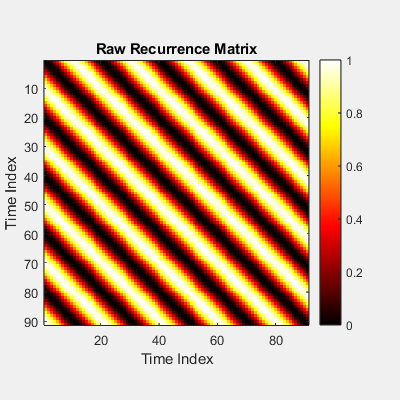

Figure 3 (Raw RM) created.


plotRM(RM);

RM_thresh = treshold_RM(RM);

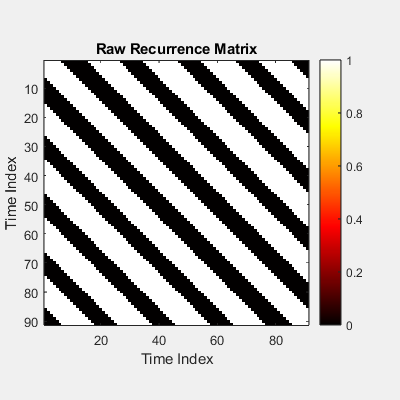

Figure 3 (Raw RM) created.


plotRM(RM_thresh);

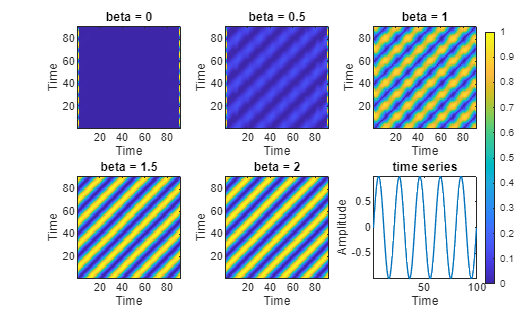

plot_betas(x,10,1);